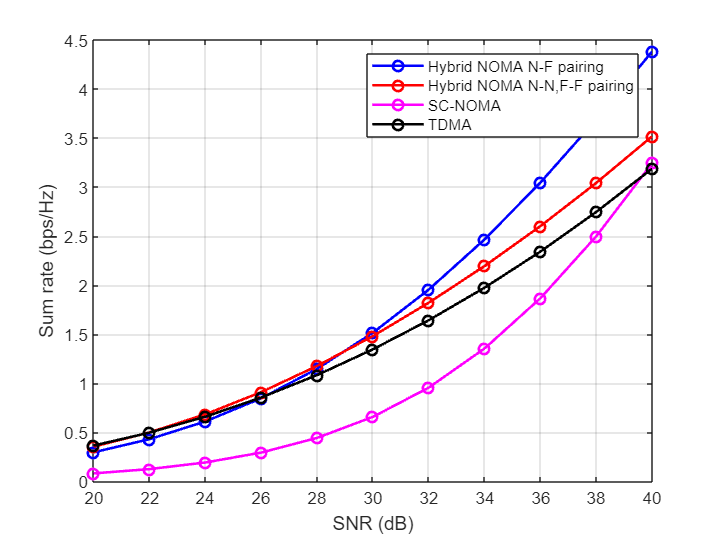

clc; clear variables; 
close all;

d1 = 10; d2 = 9;
d3 = 4; d4 = 3;

eta = 4;

N = 10^4;

h1 = sqrt(d1^-eta)*(randn(1,N)+1i*randn(1,N))/sqrt(2);
h2 = sqrt(d2^-eta)*(randn(1,N)+1i*randn(1,N))/sqrt(2);
h3 = sqrt(d3^-eta)*(randn(1,N)+1i*randn(1,N))/sqrt(2);
h4 = sqrt(d4^-eta)*(randn(1,N)+1i*randn(1,N))/sqrt(2);

g1 = (abs(h1)).^2;
g2 = (abs(h2)).^2;
g3 = (abs(h3)).^2;
g4 = (abs(h4)).^2;

SNR = 20:2:40;
snr = db2pow(SNR);

a1 = 0.7; a2 = 1-a1;

b1 = 0.7; b2 = (3/4)*(1-b1); b3 = (3/4)*(1-(b1+b2)); b4 = 1 - (b1+b2+b3);
T = 1;
epsilon = (2^T)-1;

for u = 1:length(snr)
%     a1 = min(1,epsilon*((1/snr(u)) + g1)./(g1*(1+epsilon)));
%     a2 = 1 - a1;
% 
%     a1 = min(1,epsilon*((1/snr(u)) + g1)./(g1*(1+epsilon)));
%     a2 = 1 - a1;

   
   %1-2  3-4 (n-n, f-f)
   C1(u) = mean(log2(1 + a1.*g1*snr(u)./(a2.*g1*snr(u)+1)));
   C2(u) = mean(log2(1 + a2.*g2*snr(u)));
   C3(u) = mean(log2(1 + a1.*g3*snr(u)./(a2.*g3*snr(u)+1)));
   C4(u) = mean(log2(1 + a2.*g4*snr(u)));
   
   %1-4  2-3 (n-f)
   C11(u) = mean(log2(1 + a1.*g1*snr(u)./(a2.*g1*snr(u)+1)));
   C44(u) = mean(log2(1 + a2.*g4*snr(u)));
   C22(u) = mean(log2(1 + a1.*g2*snr(u)./(a2.*g2*snr(u)+1)));
   C33(u) = mean(log2(1 + a2.*g3*snr(u)));
   
   
   %TDMA
   t1(u) = 0.25*mean(log2(1 + g1*snr(u)));
   t2(u) = 0.25*mean(log2(1 + g2*snr(u)));
   t3(u) = 0.25*mean(log2(1 + g3*snr(u)));
   t4(u) = 0.25*mean(log2(1 + g4*snr(u)));
   
%    %NOMA
   n1(u) = mean(log2(1 + b1.*g1*snr(u)./((b2+b3+b4).*g1*snr(u)+1)));
   n2(u) = mean(log2(1 + b2.*g2*snr(u)./((b3+b4).*g2*snr(u)+1)));
   n3(u) = mean(log2(1 + b3.*g3*snr(u)./(b4.*g3*snr(u)+1)));
   n4(u) = mean(log2(1 + b4.*g4*snr(u)));
%    
% %   
end


R1 = 0.5*(C1+C2+C3+C4);
R11 = 0.5*(C11+C22+C33+C44);
t = (t1+t2+t3+t4);
n = n1+n2+n3+n4;
figure;
plot(SNR,R11,'o-b','linewidth',1.5);hold on; grid on;
plot(SNR,R1,'o-r','linewidth',1.5); 
plot(SNR,n,'o-m','linewidth',1.5);
plot(SNR,t,'o-k','linewidth',1.5);

legend('Hybrid NOMA N-F pairing','Hybrid NOMA N-N,F-F pairing','SC-NOMA','TDMA');
xlabel('SNR (dB)');
ylabel('Sum rate (bps/Hz)');